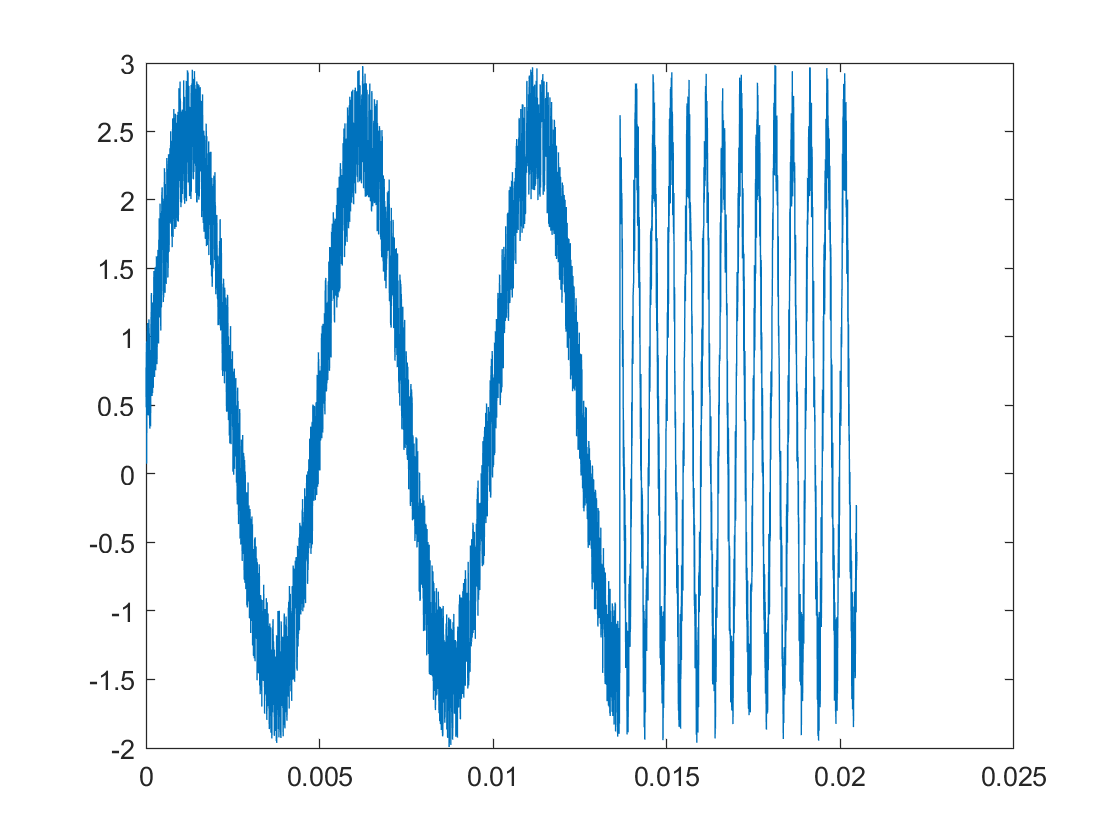

clear;
% signal
% tt=0:1e-6:0.01;
% freq=1000+100e3/0.01*tt;
% signal=10*sin(2*pi*freq.*tt);
% plot(tt,signal);
% signal 2
tt=0:5e-6:(2^12-1)*5e-6;
freq=[200*ones(size(tt(1:floor(2*length(tt)/3)))),2000*ones(size(tt(1+floor(2*length(tt)/3):length(tt))))];
signal_0=2*sin(2*pi*freq.*tt);
noise=rand(size(signal_0));
signal=signal_0+noise;
plot(tt,signal);

% signal 2

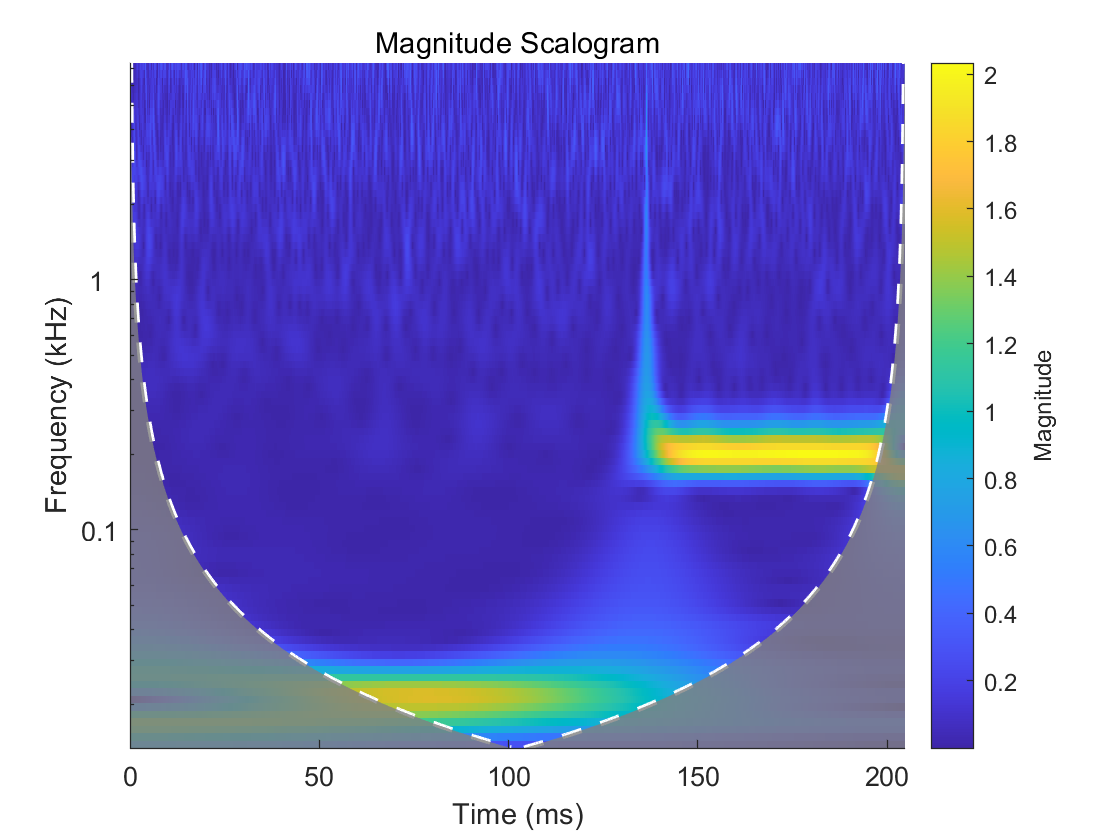

cwt(signal,'amor',20e3);

% % wavelet by db2 filter
wname = 'db2';
[LoD,HiD,LoR,HiR] = wfilters(wname);
[cA1,cD1]=dwt(signal,LoD,HiD,'mode','per');
[cA2,cD2]=dwt(cA1,LoD,HiD,'mode','per');
[cA3,cD3]=dwt(cA2,LoD,HiD,'mode','per');
[cA4,cD4]=dwt(cA3,LoD,HiD,'mode','per');
tt1=dyaddown(tt);
tt2=dyaddown(tt1);
tt3=dyaddown(tt2);
tt4=dyaddown(tt3);

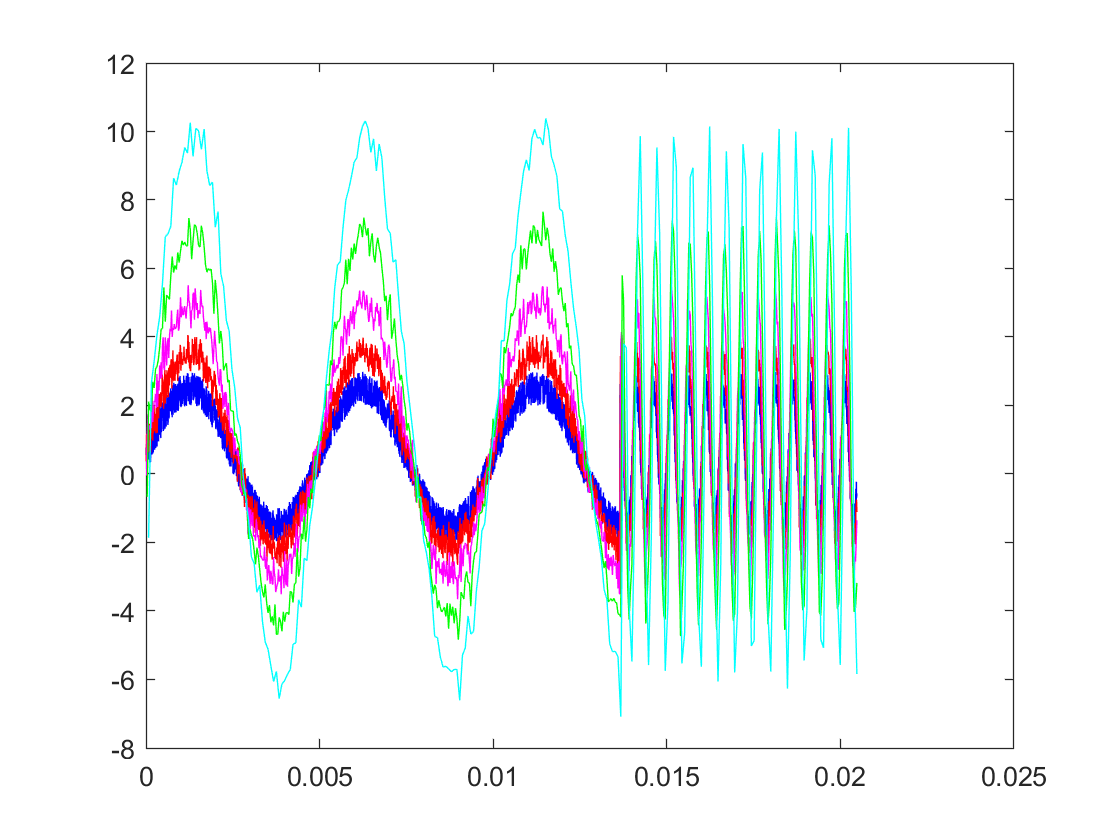

% dwt results
plot(tt,signal,'b');hold on;
plot(tt1,cA1(1:length(tt1)),'r');plot(tt2,cA2(1:length(tt2)),'m');
plot(tt3,cA3(1:length(tt3)),'g');plot(tt4,cA4(1:length(tt4)),'c');
hold off;

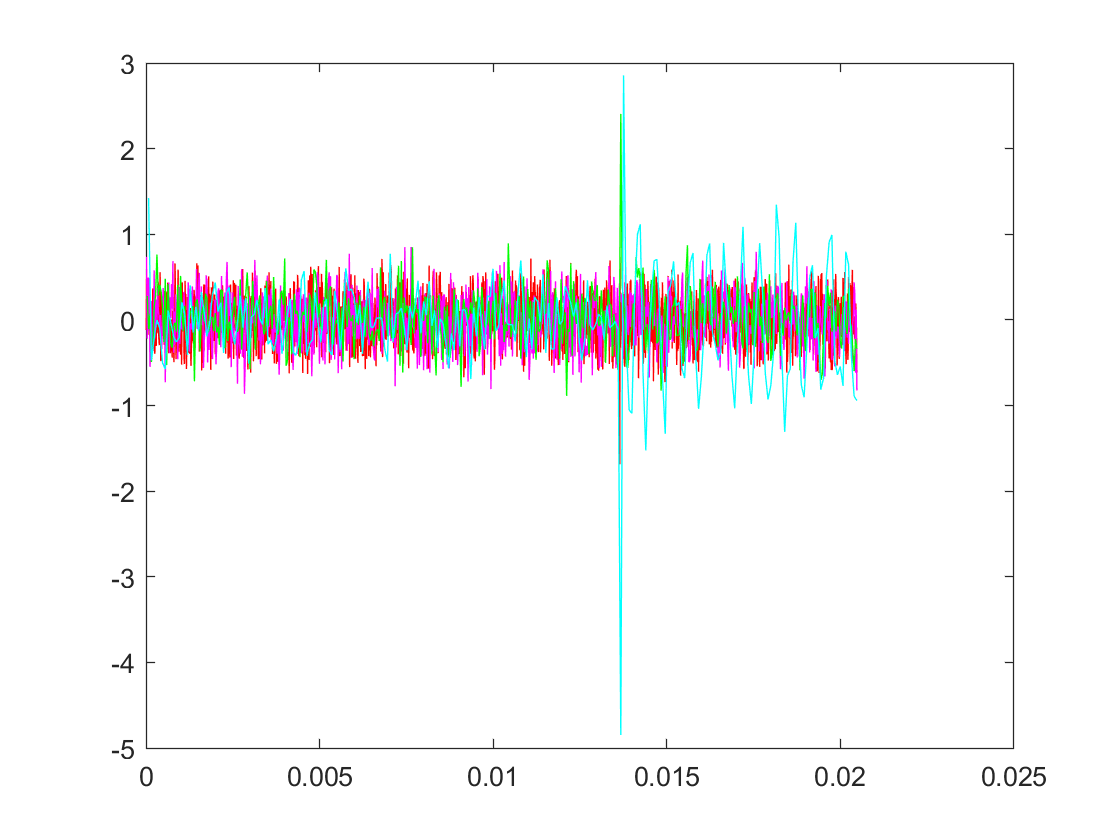

plot(tt1,cD1(1:length(tt1)),'r');hold on;plot(tt2,cD2(1:length(tt2)),'m');
plot(tt3,cD3(1:length(tt3)),'g');plot(tt4,cD4(1:length(tt4)),'c');
hold off;

% idwt 
% let cD1, cD2,cD3 =0
cA3_R=idwt(cA4,cD4,LoR,HiR,'mode','per');
cA2_R_3=idwt(cA3_R,zeros(size(cD3)),LoR,HiR,'mode','per');
cA1_R_3=idwt(cA2_R_3,zeros(size(cD2)),LoR,HiR,'mode','per');
signal_rec_3=idwt(cA1_R_3,zeros(size(cD1)),LoR,HiR,'mode','per');
% let cD1, cD2 =0
cA2_R_2=idwt(cA3_R,cD3,LoR,HiR,'mode','per');
cA1_R_2=idwt(cA2_R_2,zeros(size(cD2)),LoR,HiR,'mode','per');
signal_rec_2=idwt(cA1_R_2,zeros(size(cD1)),LoR,HiR,'mode','per');
% let cD1 =0
cA1_R_1=idwt(cA2_R_2,cD2,LoR,HiR,'mode','per');
signal_rec_1=idwt(cA1_R_1,zeros(size(cD1)),LoR,HiR,'mode','per');
% complete idwt
signal_rec=idwt(cA1_R_1,cD1,LoR,HiR,'mode','per');

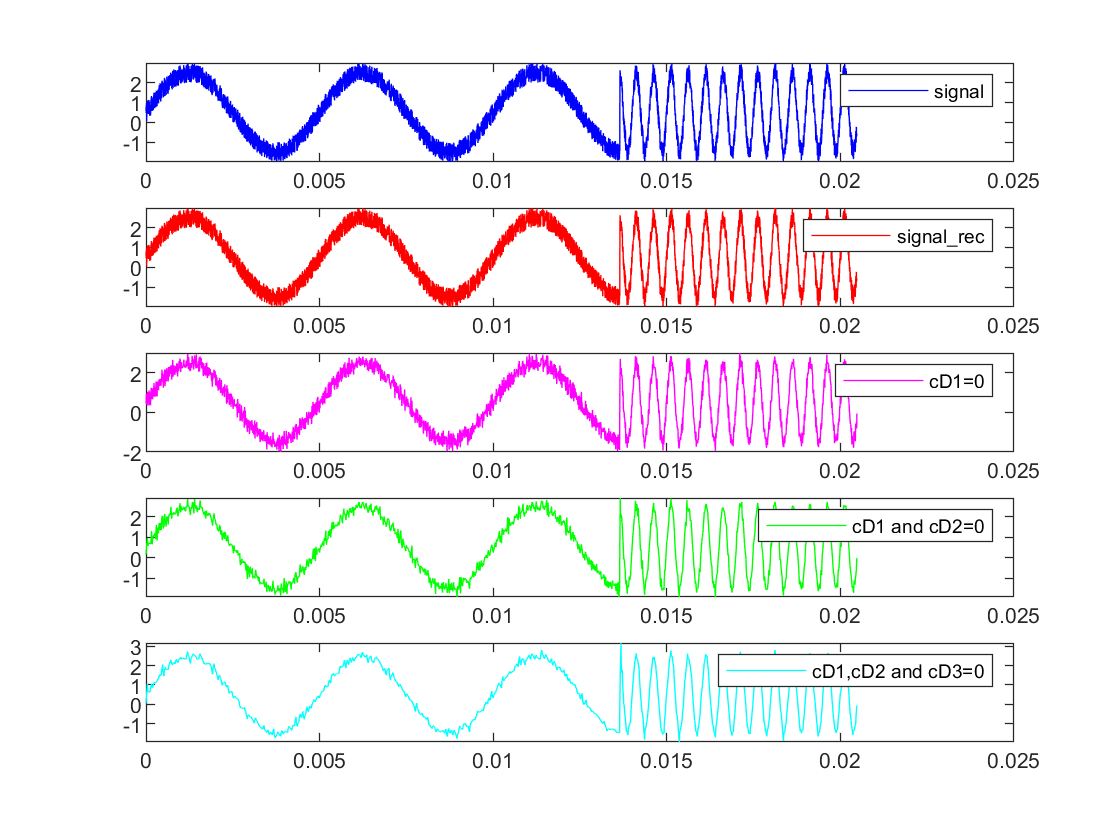

subplot(5,1,1);
plot(tt,signal,'b');legend('signal');
subplot(5,1,2);
plot(tt,signal_rec,'r');legend('signal\_rec');
subplot(5,1,3);
plot(tt,signal_rec_1,'m');legend('cD1=0');
subplot(5,1,4);
plot(tt,signal_rec_2,'g');legend('cD1 and cD2=0');
subplot(5,1,5);
plot(tt,signal_rec_3,'c');legend('cD1,cD2 and cD3=0');
hold off;

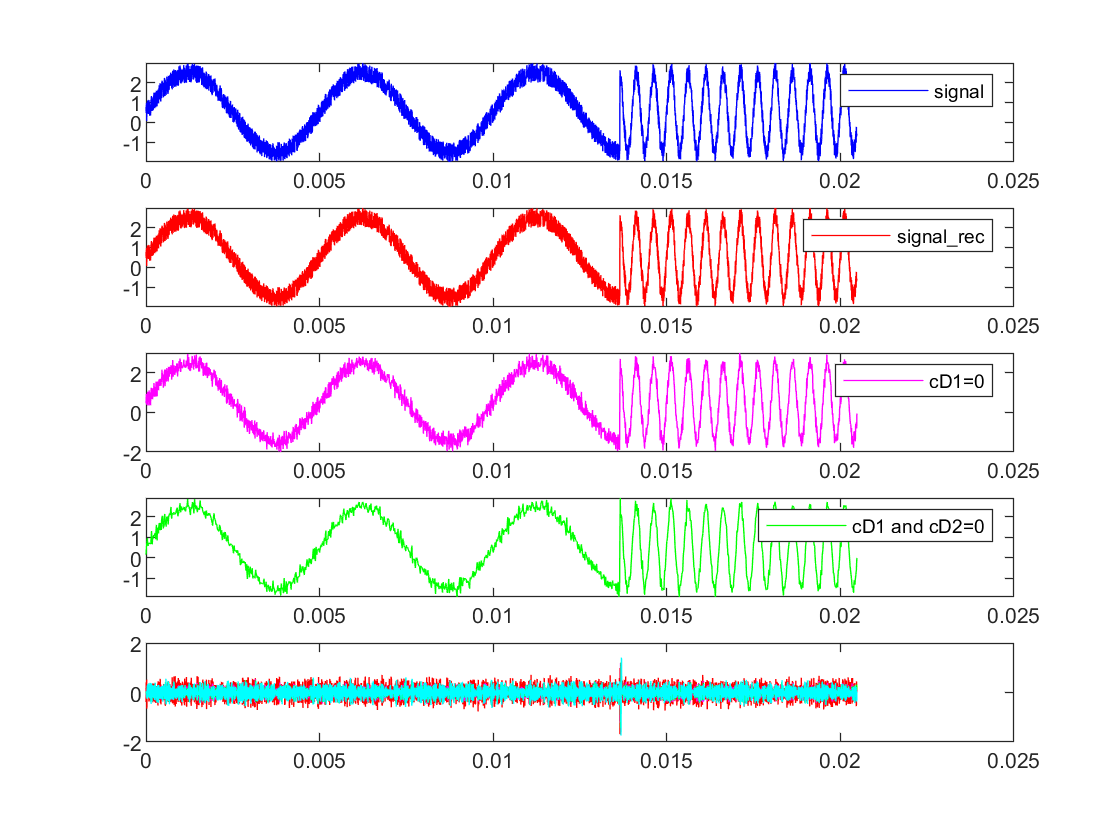

% 卷积验算，可忽略
cAA1=conv(signal,LoD);
cDD1=conv(signal,HiD);
cAA2=conv(cAA1,LoD);
cDD2=conv(cAA1,HiD);
cAA3=conv(cAA2,LoD);
cDD3=conv(cAA2,HiD);
cAA4=conv(cAA3,LoD);
cDD4=conv(cAA3,HiD);
plot(tt,signal,'b');hold on;
plot(tt,cAA1(1:length(tt)),'r');plot(tt,cAA2(1:length(tt)),'m');
plot(tt,cAA3(1:length(tt)),'g');plot(tt,cAA4(1:length(tt)),'c');
hold off;
plot(tt,cDD1(1:length(tt)),'r');hold on;plot(tt,cDD2(1:length(tt)),'m');
plot(tt,cDD3(1:length(tt)),'g');plot(tt,cDD4(1:length(tt)),'c');
hold off;

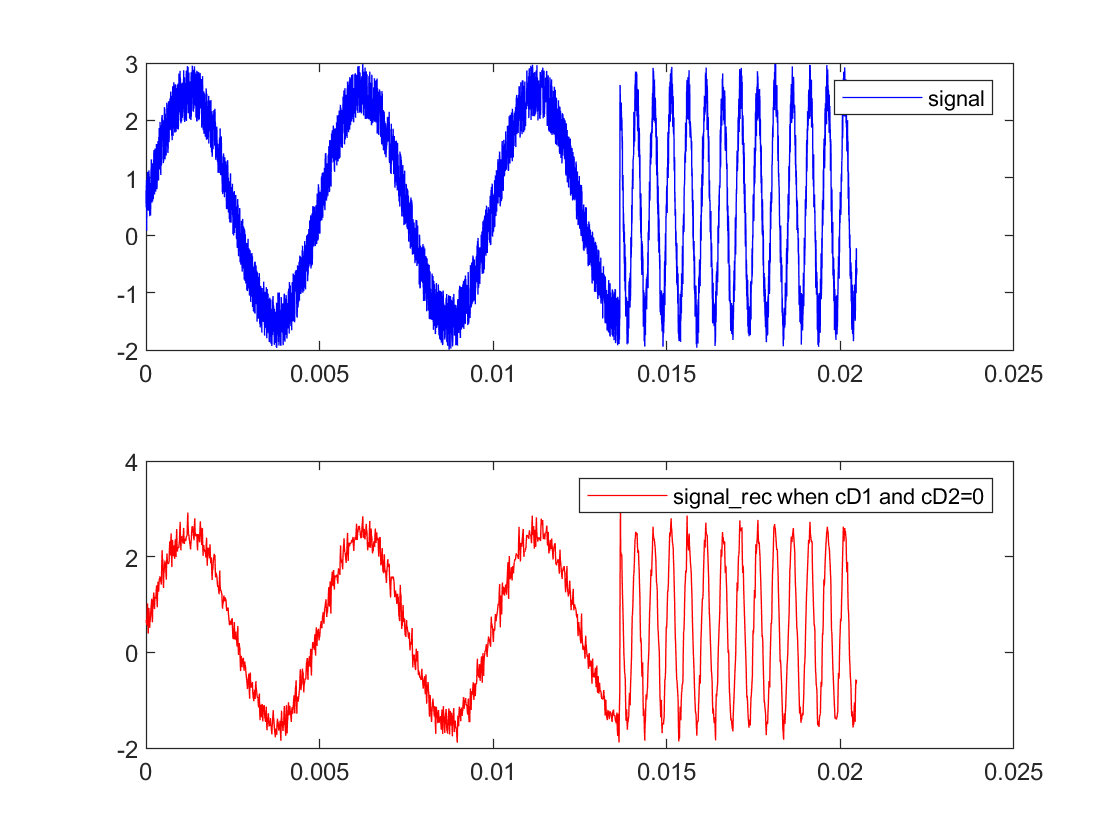

% decompose with wavedec
level=4;
[c,l]=wavedec(signal,level,LoD,HiD);
approx = appcoef(c,l,'db2');    % ca4
[cd1,cd2,cd3,cd4] = detcoef(c,l,[1 2 3 4]);
cd1_1=zeros(size(cd1));cd2_1=zeros(size(cd2));
c_1=[approx,cd4,cd3,cd2_1,cd1_1];
signal_rec_waverec=waverec(c_1,l,LoR,HiR);
figure();
subplot(2,1,1);
plot(tt,signal,'b');legend('signal');
subplot(2,1,2);
plot(tt,signal_rec_waverec,'r');legend('signal\_rec when cD1 and cD2=0');

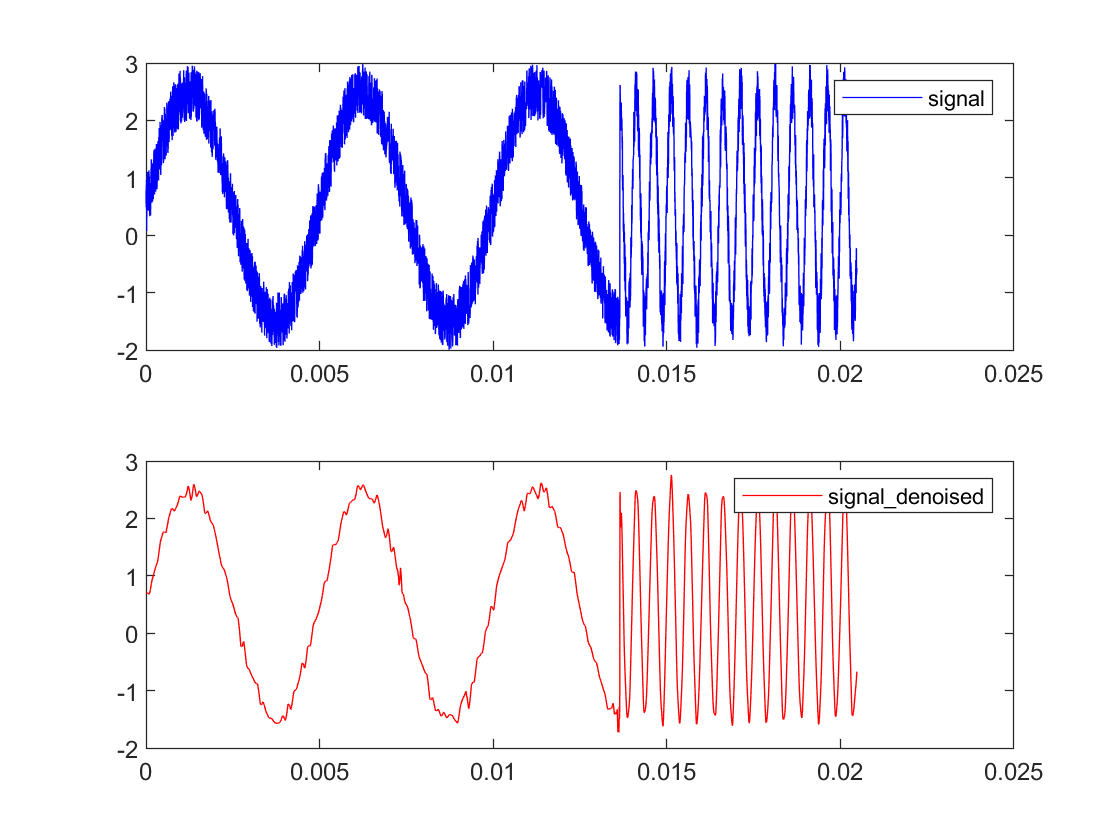

% denoise by wdenoise()
level1=4;
signal_denois=wdenoise(signal,level1,'wavelet','sym4');
figure();
subplot(2,1,1);
plot(tt,signal,'b');legend('signal');
subplot(2,1,2);
plot(tt,signal_denois,'r');legend('signal\_denoised');